close all;
clear;
clc;

## Data 1

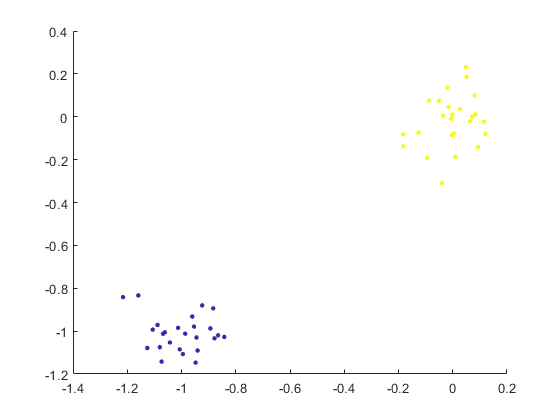

X1 = [mvnrnd([-1; -1], 0.01*eye(2, 2), 25); mvnrnd([0; 0], 0.01*eye(2, 2), 25)];
X1test = [mvnrnd([-1; -1], 0.01*eye(2, 2), 25); mvnrnd([0; 0], 0.01*eye(2, 2), 25)];

y1 = [-ones(25, 1); ones(25, 1)];
y1test = y1;

figure('NumberTitle', 'off', 'Name', 'Data set 1');
scatter(X1(:, 1), X1(:, 2), 12, y1, 'filled');

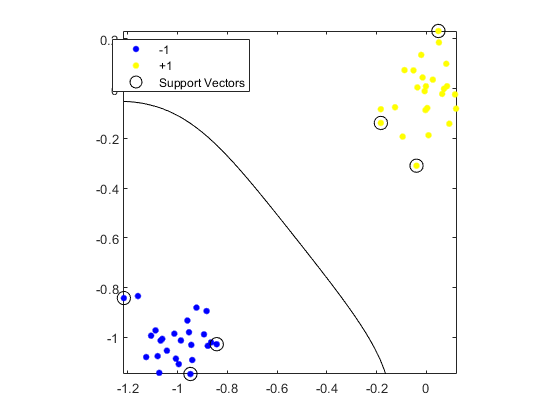


%Train the SVM Classifier
cl = fitcsvm(X1,y1,'KernelFunction','rbf','Standardize',true);

% Predict scores over the grid
d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(X1(:,1)):d:max(X1(:,1)),...
    min(X1(:,2)):d:max(X1(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(cl,xGrid);

% Predict scores over the grid on X1Test
d = 0.02;
[x11Grid,x22Grid] = meshgrid(min(X1test(:,1)):d:max(X1test(:,1)),...
    min(X1test(:,2)):d:max(X1test(:,2)));
xxGrid = [x11Grid(:),x22Grid(:)];
[~,scoresTest] = predict(cl,xxGrid);

% Plot the data and the decision boundary
figure('NumberTitle', 'off', 'Name', 'Data set 1 Decision Boundary');
h1(1:2) = gscatter(X1(:,1),X1(:,2),y1,'by','.');
hold on;
h1(3) = plot(X1(cl.IsSupportVector,1),X1(cl.IsSupportVector,2),'ko','MarkerSize',10);
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h1,{'-1','+1','Support Vectors'});
axis equal
hold off

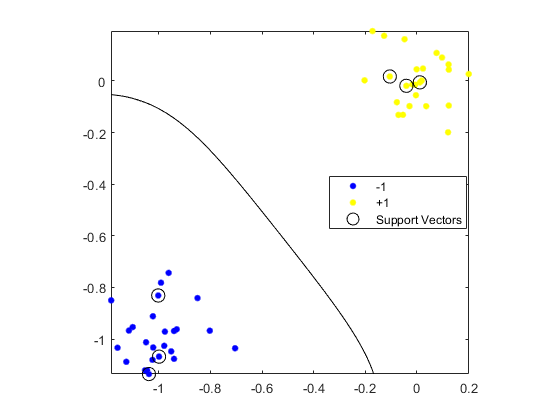


% Plot the data and the decision boundary on Test X1
figure('NumberTitle', 'off', 'Name', 'Data set 1 Test Decision Boundary');
h11(1:2) = gscatter(X1test(:,1),X1test(:,2),y1,'by','.');
hold on;
h11(3) = plot(X1test(cl.IsSupportVector,1),X1test(cl.IsSupportVector,2),'ko','MarkerSize',10);
contour(x11Grid,x22Grid,reshape(scoresTest(:,2),size(x11Grid)),[0 0],'k');
legend(h11,{'-1','+1','Support Vectors'});
axis equal
hold off

## Data 2

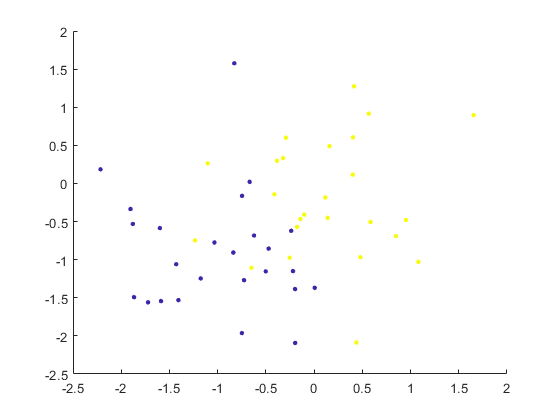

X2 = [mvnrnd([-1; -1], 0.5*eye(2, 2), 25); mvnrnd([0; 0], 0.5*eye(2, 2), 25)];
X2test = [mvnrnd([-1; -1], 0.5*eye(2, 2), 25); mvnrnd([0; 0], 0.5*eye(2, 2), 25)];

y2 = [-ones(25, 1); ones(25, 1)];
y2test = y2;

figure('NumberTitle', 'off', 'Name', 'Data set 2');
scatter(X2(:, 1), X2(:, 2), 12, y2, 'filled');

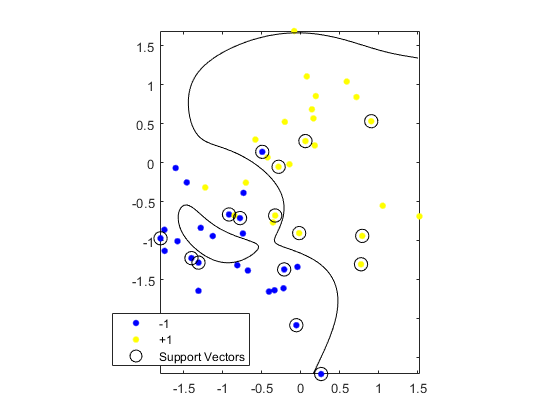


%Train the SVM Classifier
c2 = fitcsvm(X2,y2,'KernelFunction','rbf',...
    'BoxConstraint',Inf,'ClassNames',[-1,1]);

% Predict scores over the grid
d = 0.02;
[x1Grid,x2Grid] = meshgrid(min(X2(:,1)):d:max(X2(:,1)),...
    min(X2(:,2)):d:max(X2(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(c2,xGrid);

% Predict scores over the grid on X2Test
d = 0.02;
[x11Grid,x22Grid] = meshgrid(min(X2test(:,1)):d:max(X2test(:,1)),...
    min(X2test(:,2)):d:max(X2test(:,2)));
xxGrid = [x11Grid(:),x22Grid(:)];
[~,scoresTest] = predict(c2,xxGrid);

% Plot the data and the decision boundary on Test X2
figure('NumberTitle', 'off', 'Name', 'Data set 2 Test Decision Boundary');
h22(1:2) = gscatter(X2test(:,1),X2test(:,2),y2,'by','.');
hold on;
h22(3) = plot(X2test(c2.IsSupportVector,1),X2test(c2.IsSupportVector,2),'ko','MarkerSize',10);
contour(x11Grid,x22Grid,reshape(scoresTest(:,2),size(x11Grid)),[0 0],'k');
legend(h22,{'-1','+1','Support Vectors'});
axis equal
hold off

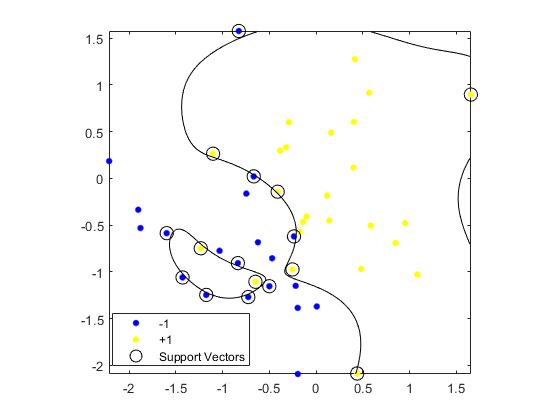


% Plot the data and the decision boundary
figure('NumberTitle', 'off', 'Name', 'Data set 2 Decision Boundary');
h2(1:2) = gscatter(X2(:,1),X2(:,2),y2,'by','.');
hold on
h2(3) = plot(X2(c2.IsSupportVector,1),X2(c2.IsSupportVector,2),'ko','MarkerSize',10);
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h2,{'-1','+1','Support Vectors'});
axis equal
hold off

## Data 3

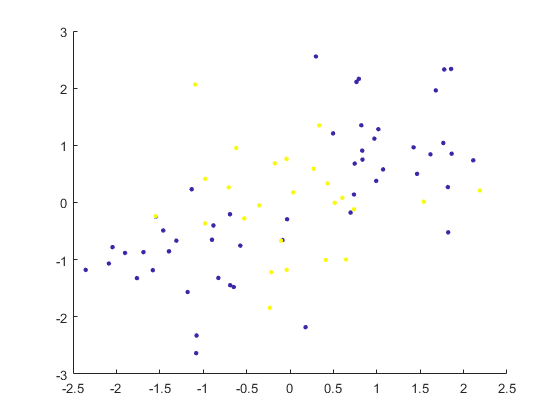

X3 = [mvnrnd([-1; -1], 0.5*eye(2, 2), 25); mvnrnd([0; 0], 0.5*eye(2, 2), 25); mvnrnd([1; 1],0.5*eye(2, 2), 25)];
X3test = [mvnrnd([-1; -1], 0.5*eye(2, 2), 25); mvnrnd([0; 0], 0.5*eye(2, 2), 25); mvnrnd([1; 1],0.5*eye(2, 2), 25)];

y3 = [-ones(25, 1); ones(25, 1); -ones(25, 1)];
y3test = y3;

figure('NumberTitle', 'off', 'Name', 'Data set 3');
scatter(X3(:, 1), X3(:, 2), 12, y3, 'filled');

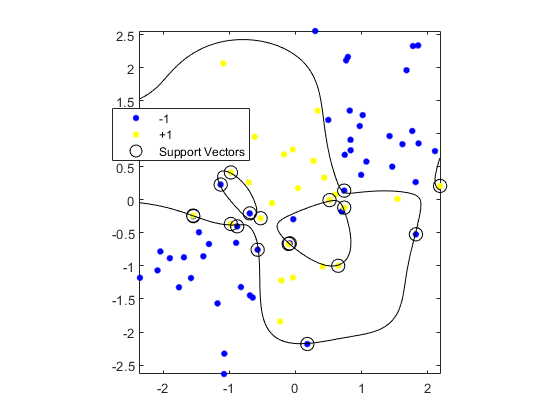


%Train the SVM Classifier
c3 = fitcsvm(X3,y3,'KernelFunction','rbf',...
    'BoxConstraint',Inf,'ClassNames',[-1,1]);

% Predict scores over the grid
d = 0.01;
[x1Grid,x2Grid] = meshgrid(min(X3(:,1)):d:max(X3(:,1)),...
    min(X3(:,2)):d:max(X3(:,2)));
xGrid = [x1Grid(:),x2Grid(:)];
[~,scores] = predict(c3,xGrid);

% Predict scores over the grid on X3Test
d = 0.01;
[x11Grid,x22Grid] = meshgrid(min(X3test(:,1)):d:max(X3test(:,1)),...
    min(X3test(:,2)):d:max(X3test(:,2)));
xxGrid = [x11Grid(:),x22Grid(:)];
[~,scoresTest] = predict(c3,xxGrid);


% Plot the data and the decision boundary
figure('NumberTitle', 'off', 'Name', 'Data set 3 Decision Boundary');
h3(1:2) = gscatter(X3(:,1),X3(:,2),y3,'by','.');
hold on
h3(3) = plot(X3(c3.IsSupportVector,1),X3(c3.IsSupportVector,2),'ko','MarkerSize',10);
contour(x1Grid,x2Grid,reshape(scores(:,2),size(x1Grid)),[0 0],'k');
legend(h3,{'-1','+1','Support Vectors'},'Location','Best');
axis equal
hold off

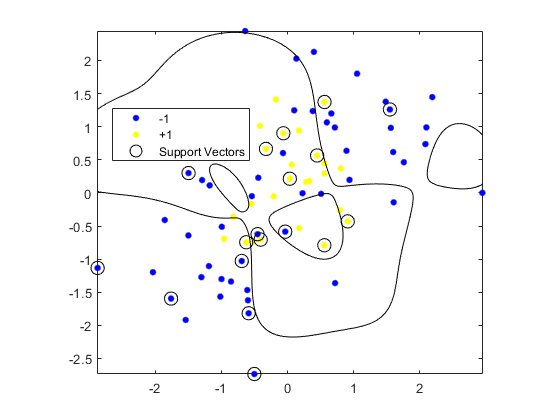


% Plot the data and the decision boundary on Test X3
figure('NumberTitle', 'off', 'Name', 'Data set 3 Test Decision Boundary');
h33(1:2) = gscatter(X3test(:,1),X3test(:,2),y3,'by','.');
hold on;
h33(3) = plot(X3test(c3.IsSupportVector,1),X3test(c3.IsSupportVector,2),'ko','MarkerSize',10);
contour(x11Grid,x22Grid,reshape(scoresTest(:,2),size(x11Grid)),[0 0],'k');
legend(h33,{'-1','+1','Support Vectors'});
axis equal
hold off